# plot performance

绘制不同lambda下flnnscc在yale10, yale15上的表现

% % 记录评估指标
% for i = 1:10
%     ca(i)=max(CA(:,:,i),[],'all');
%     nmi(i)=max(NMI(:,:,i),[],'all');
%     ar(i)=max(AR(:,:,i),[],'all');
%     f1(i)=max(F1(:,:,i),[],'all');
% end

绘制折线图

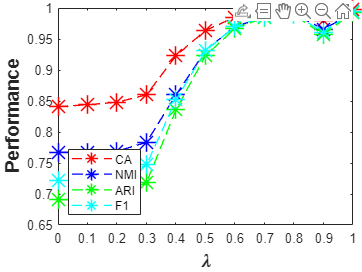

clear
load performance_usps.mat

x = 0:0.1:1;
plot(x,ca,"Color",'r','LineStyle','--','LineWidth',1,'Marker','*','MarkerSize',14)
hold on
plot(x,nmi,"Color",'b','LineStyle','--','LineWidth',1,'Marker','*','MarkerSize',14)
hold on
plot(x,ar,"Color",'g','LineStyle','--','LineWidth',1,'Marker','*','MarkerSize',14)
hold on
plot(x,f1,"Color",'c','LineStyle','--','LineWidth',1,'Marker','*','MarkerSize',14)
set(gca,'LooseInset',[0,0,0,0]);  % 去白边
legend({'CA','NMI','ARI','F1'},'location','southwest');
xlabel('\lambda','FontSize',14,'FontWeight','bold');
xticks(0:0.1:1);
ylabel('Performance','FontSize',14,'FontWeight','bold');